## Assignment 2

% Return the number of iterations needed for a set of parameter c
function it = fractal(c)
    z = 0.0;
    nit = 100;
    it = zeros(size(c));
    for i = 1:nit
        z = z.^2 + c;
        % For points in the Mandelbrot, abs(z)<2, condition always False,
        % so the final value of it is 0.
        % When z after i iterations have abs(z)>2, this i will be saved
        % and no more updates.
        it(abs(z) > 2 & it == 0) = i;
    end
end

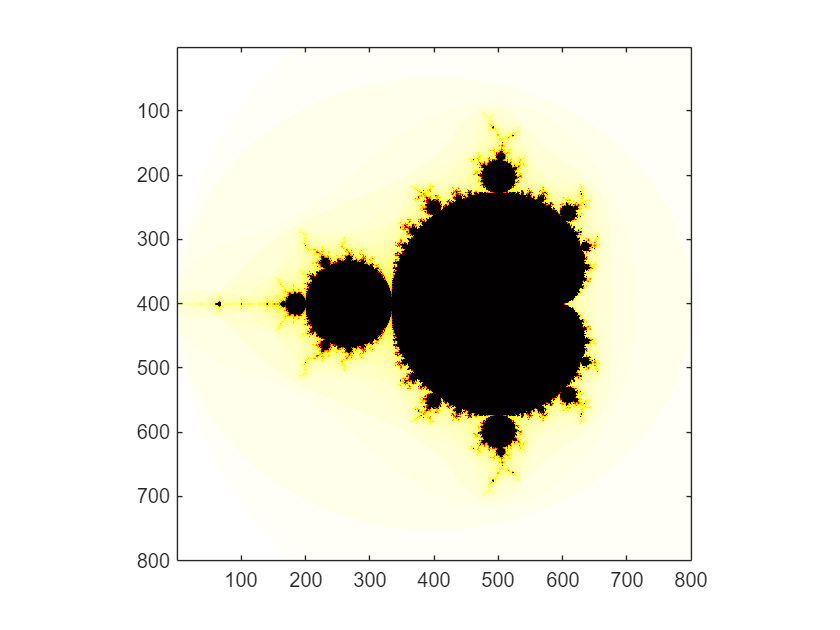

% Viualize the Mandelbrot set
x0 = -2.0;   x1 = 1.0;
y0 = -1.5; y1 = 1.5; % Just to make the plot square
N = 800; % Resolution
[x,y] = meshgrid(linspace(x0, x1, N), linspace(y0, y1, N));

c = x + 1i * y;
it_set = fractal(c);
% Inverse the color outside the Mandelbrot to have more divergent c painted
% lighter color.
it_set (it_set ~= 0) = 100 - it_set (it_set ~= 0);

figure;
imagesc(it_set);
colormap hot
axis square
saveas(gcf, 'data/Visualization', 'png');

% Indicator function at Re(z)=x
function fn = indicator_fn_x(x)
    % Anonymous function carry out the iteration
    fn = @(y) (fractal(x + 1i * y) > 0) * 2 - 1; 
end

% Bisection function to find the boundray above real axis. If indicator
% function changes sign for more than one, just output one that continuous
% to the former x. 
% tol: the minimum dsitance between lower bound and upper bound
function m = bisection(fn_f, lo_b, up_b, tol)
    s = lo_b;
    e = up_b;
    while abs(e-s) > tol
        mid = (s+e)/2;
        f_m = fn_f(mid);
        if fn_f(e)*f_m < 0 % Calculate and compare the upper bound e so that 
            % for two boundary points at one x, pick the one with larger 
            % imaginary part.
            s = mid;
        else
            e = mid;
        end        
    end
    m = (s+e)/2;

end

function l = poly_len(p, s, e)
    dp = polyder(p); % Calculate the deritive of the polynomial function.
    ds = @(x) sqrt(polyval(dp, x).^2 + 1);
    l = integral(ds, s, e);
end

n_boundary = 1e4;
tol = 1e-7;
bp_set = zeros(1,n_boundary);
x_set = linspace(x0, x1, n_boundary);
for index = 1:length(x_set)
    x = x_set(index);
    fn_x = indicator_fn_x(x);
    y = bisection(fn_x, 0, 1, tol); % y in range (0,1)
    bp = x + 1i * y;
    bp_set(index) = bp;
end

left_flat = imag(bp_set) < tol; % Discard the flat region on the left,
% which represents that current tol cannot show the boundary points which is
% close to zero.
true_boundary = bp_set(~left_flat);

Re = real(true_boundary);  
Im = imag(true_boundary);  

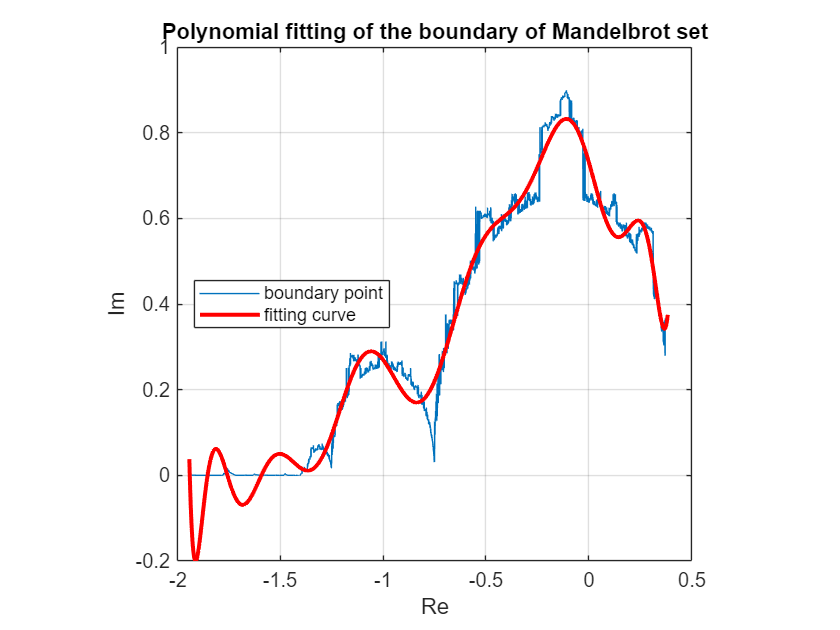

p = polyfit(Re, Im, 15);
% Select only x in the region of boundary for fitting
x_fit = linspace(min(Re), max(Re), 1000); 
y_fit = polyval(p, x_fit);

figure;
plot(Re, Im, '-', 'DisplayName', 'boundary point');
hold on;
plot(x_fit, y_fit, 'r-', 'LineWidth', 2, 'DisplayName', 'fitting curve'); 
xlabel('Re');
ylabel('Im');
title('Polynomial fitting of the boundary of Mandelbrot set');
legend('show', 'Location', 'west');
axis square;
grid on;
hold off;
saveas(gcf, 'data/fitting', 'png');

l = poly_len(p, min(Re), max(Re)) % Integrate the fitting curve

l = 3.6124

disp(l)

    3.6124

